Question: 1.a)

syms q;
I = [1 0 0; 0 1 0;0 0 1];
A = [0.2 0 0; 0 0.5 0; 0 1 0.6];
B = [0; 1; 0];
C = [0 1 0];
D = 0;

G_q = C*inv(q*I-A)*B + D

$$G\_q = \frac{2}{2\,q-1}$$

[Num,Den] = ss2tf(A,B,C,D);
G_z = tf(Num,Den,1,"Variable","z^-1")

G_z =
 
      z^-1 - 0.8 z^-2 + 0.12 z^-3
  ------------------------------------
  1 - 1.3 z^-1 + 0.52 z^-2 - 0.06 z^-3
 
Sample time: 1 seconds
Discrete-time transfer function.



zpk(G_z)

ans =
 
     z^-1 (1-0.6z^-1) (1-0.2z^-1)
  -----------------------------------
  (1-0.6z^-1) (1-0.5z^-1) (1-0.2z^-1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



 The orders of $G\left(q^{-1} \right)$ (order = 1), $G\left(z^{-1} \right)$(order = 3) and the SS model (order = 3) in (1) does not match. For $G\left(z^{-1} \right)$ two identical poles and zeroes gets cancelled resulting in oreder = 1, therefore it has the same order as that of $G\left(q^{-1} \right)$. But the given model is not a minimal realization model, as a result the order doesn't match with  $G\left(q^{-1} \right)$ or $G\left(z^{-1} \right)$.

Question: 2.a)

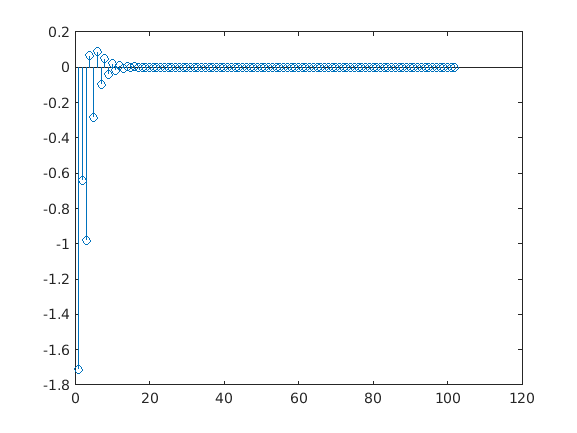

Ad = [0.3866, -0.1633; -0.1633, -0.6321];
Bd = [1.438; 0.3252];
C = [-0.7549, 1.37];
D = -1.712;

[num,den] = ss2tf(Ad,Bd,C,D,1);
G_tf = tf(num,den,1);
ircoeff = impulse(G_tf ,101);
stem(ircoeff)

Question: 2.b)

Hir = hankel(ircoeff(2:51), ircoeff(51:end));

% SVD of Hankel matrix
[Uh, Sh, Vh] = svd(Hir);
nx = rank(Hir);

% Estimate obsrv and ctrb matrices
Obn = Uh(:,1:nx) * sqrt(Sh(1:nx, 1:nx));
Cbn = sqrt(Sh(1:nx,1:nx)) * Vh(:,1:nx)';

% Estimate SS matrices
D2 = ircoeff(1); 
C2 = Obn(1,:); 
Bd2 = Cbn(:,1);
Ad2 = pinv (Obn(1:end-1,:)) * Obn(2:end,:);

Ghat_ss = ss(Ad2, Bd2, C2, D2, 1)

Ghat_ss =
 
  A = 
            x1       x2
   x1   0.5101  -0.3382
   x2   0.3382  -0.7556
 
  B = 
            u1
   x1  -0.9487
   x2     0.51
 
  C = 
           x1      x2
   y1  0.9487    0.51
 
  D = 
           u1
   y1  -1.712
 
Sample time: 1 seconds
Discrete-time state-space model.



The above output describes the A, B, C, D for the SS realization from the IR data..

Question: 2.c)

Ghat_tf = tf(Ghat_ss)

Ghat_tf =
 
  -1.712 z^2 - 1.06 z - 0.676
  ---------------------------
    z^2 + 0.2455 z - 0.271
 
Sample time: 1 seconds
Discrete-time transfer function.



G_tf

G_tf =
 
  -1.712 z^2 - 1.06 z - 0.676
  ---------------------------
    z^2 + 0.2455 z - 0.271
 
Sample time: 1 seconds
Discrete-time transfer function.



We can see that TF corresponding to the State-Space model in question 2.b) obtained using Ho and Kalman’s algorithm is the same as the TF corresponing to the given original State-Space model. Therefore they are identical.

Question: 2.d)

[num, den, Ghat_ss] = KungsAlgorithm(G_tf);
Ghat_ss

Ghat_ss =
 
  A = 
            x1       x2
   x1   0.5087   -0.344
   x2    0.344  -0.7476
 
  B = 
           u1
   x1  -0.939
   x2  0.5102
 
  C = 
           x1      x2
   y1   0.939  0.5102
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



The above output describes the A, B, C, D for the SS model from the obtained input-output data and using Kung’s algorithm...

Num = [];
Den = [];

for i =1:200
    [num, den, Ghat_ss] = KungsAlgorithm(G_tf);  % user-defined function implementing Kung's Algo for order = 2..
    Num = [Num;num];
    Den = [Den;den];
end

mean_num = mean(Num);
std_num = std(Num);

mean_den = mean(Den);
std_den = std(Den);

The model obtained by Kung's algorithm is as follows,

       
$$\hat{G\;} \left(z\right)\;\;=\;\frac{-\;0\ldotp 6401\;\left(\pm \;0\ldotp 0206\right)\;z\;-\;1\ldotp 1328\;\left(\pm \;0\ldotp 0224\right)}{z^2 \;+\;0\ldotp 2365\;\left(\pm \;0\ldotp 0170\right)\;z\;-\;0\ldotp 2659\;\left(\pm \;0\ldotp 0185\right)}$$


Question: 2.e)

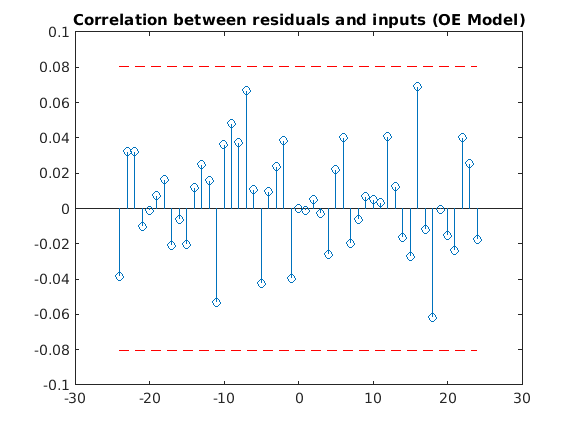

uk = idinput(1023,'PRBS');
ykstar = lsim(G_tf,uk);
    
ek = randn([1023,1]);
noise_var = var(ykstar)/10;
yk = ykstar + ek*sqrt(noise_var);
   
dataset = iddata(yk,uk,1);
[Ztrain,Tr] = detrend(dataset,0);

%..99% significance levels
clim = 2.58/sqrt(length(Ztrain.y));

% Output-error model:
mod_oe = oe(Ztrain ,[3 2 0]);
% present(mod_oe);

yhat_oe = predict(mod_oe , Ztrain );       % Predictions on training data
err_oe = pe(mod_oe , Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_oe = xcov(err_oe.y, Ztrain.u,24,'coeff');
acf_oe = xcov(err_oe.y,20,'coeff');

% Plot
figure;
stem( -24:24 , cross_corr_oe );
hold on;
plot([ -24 24] ,[1 1]* clim ,'r--' ,[-24 24] ,[ -1 -1]*clim ,'r--')
title('Correlation between residuals and inputs (OE Model)')

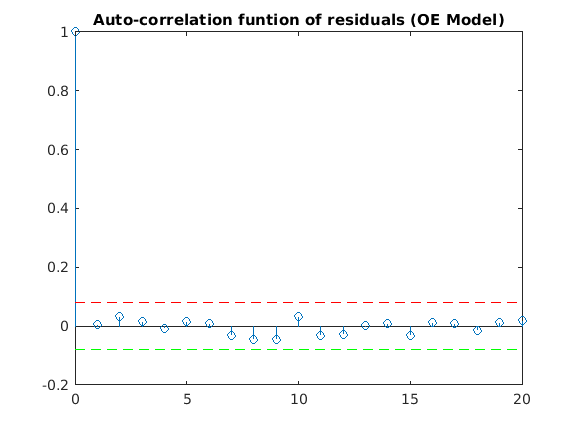

figure;
stem((0:20) ,acf_oe (21:end));
hold on;
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (OE Model)')

Output error model estimated using nk = 1 (delay) and nb = nf = 2 is as follows,

  
$$\hat{G\;} \left(z\right)\;=\;\frac{-\;1\ldotp 73\;\left(\pm \;0\ldotp 0212\right)\;z^2 \;-\;1\ldotp 155\;\left(\pm \;0\ldotp 03984\right)\;z-0\ldotp 7607\;\left(\pm 0\ldotp 039\right)}{z^2 \;+\;0\ldotp 2749\;\left(\pm \;0\ldotp 01654\right)\;z\;-\;0\ldotp 2653\;\left(\pm \;0\ldotp 01619\right)}$$


Question: 2.f)

Comparing the TF of the OE model and Kung's model, we can see that the variability (standard deviations) of coefficients in denominator of the TF is comparitively higher for OE model. Therefore, we can say that OE model is more precise and accurate.

Question: 3.c)

Gs = tf([4],[24 11 1]);
Gz = c2d(Gs,1,'zoh')

Gz =
 
   0.07169 z + 0.06154
  ----------------------
  z^2 - 1.599 z + 0.6323
 
Sample time: 1 seconds
Discrete-time transfer function.



-- Therefore, the above G(z) is equal to the G(z) that we obtained by hand in 3.a)

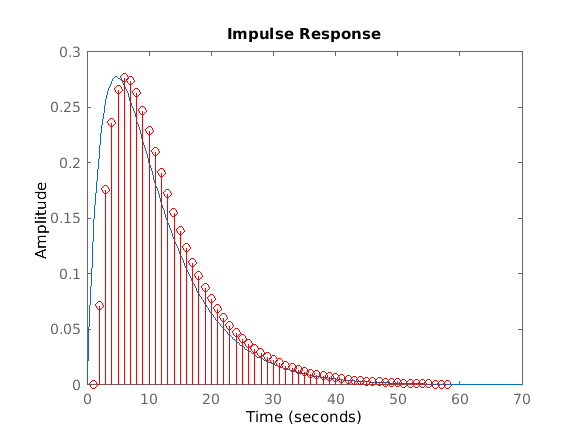

figure;
impulse(Gs);
hold on;
stem(impulse(Gz), 'Color', 'r');

As you can see, from the above plot, impulse response of continuos system doesn't coincide with the output of discrete system. Hence,  $g\left\lbrack k\right\rbrack \not= g\left(t\right){\left|\right.}_{t=\textrm{kT}}$

User-defined functions used in this script are as follows:

function [num, den, Ghat_ss] = KungsAlgorithm(G_tf)

    uk = idinput(1023,'PRBS');
    ykstar = lsim(G_tf,uk);
    
    ek = randn([1023,1]);
    noise_var = var(ykstar)/10;
    yk = ykstar + ek*sqrt(noise_var);
    
    dataset = iddata(yk,uk,1);
    
    [Ztrain,Tr] = detrend(dataset,0);
    
    % Estimate impulse response PRBS input-output
    irestoptions = impulseestOptions;
    irestoptions.Advanced.AROrder = 0;
    model = impulseest(Ztrain,irestoptions);
    
    [irmeas,kvec,~,ir_sd] = impulse(model,100);
    % stem(irmeas, 'markerfacecolor', 'b');
    
    %% Identification
    % Hankel matrix and its SVD
    Hir = hankel(irmeas(2:51), irmeas(51:end));
    [Uh,Sh,Vh] = svd(Hir,'econ');
    
    % Plot the resulting singular values to guess the order
    figure;
    % stem((1:50), diag(Sh), 'markerfacecolor', 'b')
    
    % Estimate obsrv and ctrb matrices
    nx = 2;
    Obnhat = Uh(:,1:nx) * sqrt(Sh(1:nx,1:nx));
    Cbnhat = sqrt(Sh(1:nx,1:nx)) * Vh(:,1:nx)';
    
    % Estimate SS matrices
    Dhat = 0; 
    Chat = Obnhat(1,:);
    Bhat = Cbnhat(:,1);
    Ahat = pinv(Obnhat(1:end-1,:)) * Obnhat(2:end,:);
    
    % Reconstruct the TF
    Ghat_ss = ss(Ahat,Bhat,Chat,Dhat,1);
    Ghat_tf = tf(Ghat_ss);
    
    [num,den] = tfdata(Ghat_tf,'v');
end